# 'plane' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'plane.pov', 'image_file', 'plane.png');
    % Camera
    pl.camera('angle', 50, 'location', [7 11 8.2], 'look_at', [0 0 1], 'type', 'perspective');
    
    % Lights
    % Point
    pl.light('location', [9 9 8], 'color', [3 3 3], 'shadowless', false);
    
    % Point with area
    pl.light('location', [1 -1 5], 'color', [3 3 3], 'area_light', true, 'axis1', [10 0 0], 'axis2', [0 0 10], 'size1', 2, 'size2', 2, 'shadowless', false, 'visible', true, 'shape_color', [0.1 0.1 0.1 0.7], ...
             'adaptive', 4, 'area_illumination', true, 'jitter', false, 'circular', false, 'orient', false);

    % Spotlight with area
    pl.light('type', 'spotlight', 'location', [0 4 6], 'point_at', [1 3 4.5], 'color', [3 3 3], 'area_light', true, 'axis1', [10 0 0], 'axis2', [0 0 10], 'size1', 2, 'size2', 2, 'shadowless', false, 'visible', true, 'shape_color', [0.1 0.1 0.1 0.7], ...
             'adaptive', 4, 'area_illumination', false, 'jitter', false, 'circular', false, 'orient', false);
    
    % Axis
    pl.axis('length', [6 6 5]);
   
    % Textures
    finish = "phong 1 reflection {0.02 metallic 0.8}";
    tex_pink   = pl.declare("tex_pink",   pl.texture('pigment_odd', [0.05 0.05 0.05], 'pigment_even', [0.8 0.2 0.3], 'finish', finish));
    tex_green  = pl.declare("tex_green",  pl.texture('pigment_odd', [0.05 0.05 0.05], 'pigment_even', [0.0 0.3 0.0], 'finish', finish));
    tex_blue   = pl.declare("tex_blue",   pl.texture('pigment_odd', [0.05 0.05 0.05], 'pigment_even', [0.0 0.1 0.3], 'finish', finish));    
    tex_yellow = pl.declare("tex_yellow", pl.texture('pigment_odd', [0.05 0.05 0.05], 'pigment_even', [0.3 0.3 0.0], 'finish', finish));
    tex_gray   = pl.declare("tex_gray",   pl.texture('pigment_odd', [0.01 0.01 0.01], 'pigment_even', [0.02 0.02 0.02], 'finish', finish));

    % Floor
    pl.plane('normal', [0,0,1], 'texture', tex_gray);

    % Shelfs    
    pl.plane('normal', [0,0,1], 'limits', [-1 -1 4 4], 'texture', tex_pink,   'translate', [0 0 1]);
    pl.plane('normal', [0,0,1], 'limits', [-1 -1 3 3], 'texture', tex_yellow, 'translate', [0 0 2]);
    pl.plane('normal', [0,0,1], 'limits', [-1 -1 2 2], 'texture', tex_green,  'translate', [0 0 3]);
    pl.plane('normal', [0,0,1], 'limits', [-1 -1 1 1], 'texture', tex_blue,   'translate', [0 0 4]);

pl.scene_end();

#### Render and display

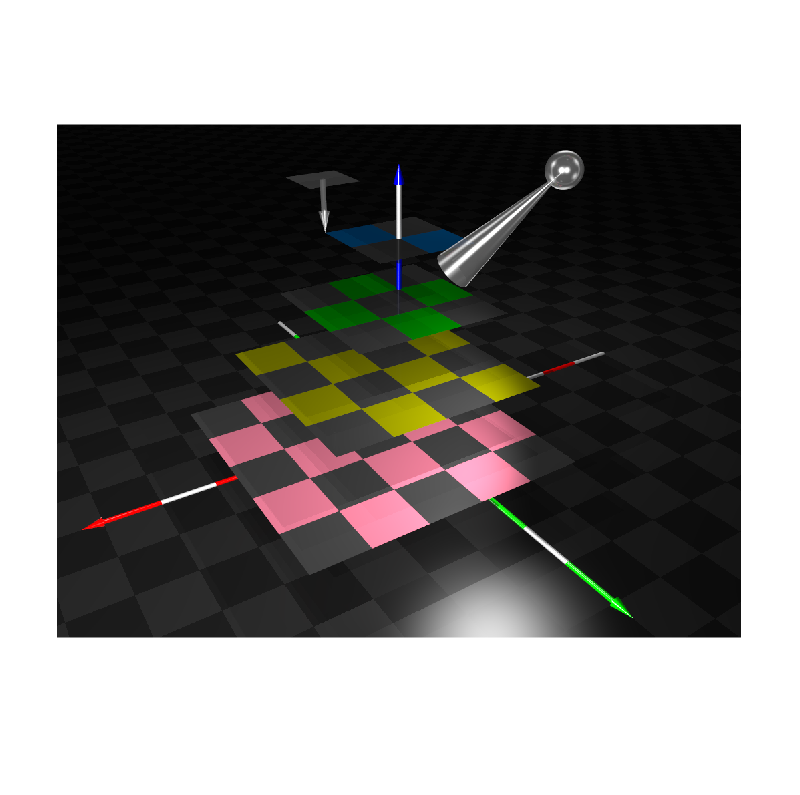

image = pl.render();
imshow(image);

#### Elapsed time


toc

Elapsed time is 5.117734 seconds.
